## Parte 4 - Speech Quantiation 

## Exercício 4.1

Abaixo a função de cálculo de SNR. 

function        [s_n_r,e] = snr_mcclellan(xh,x)
%        Fucntion to compute signal-to-noise ratio
%        [s_n_r,e] = snr(xh,x)
%               xh = quantized signal
%               x=unquantized signal
%               e=quantization error signal
%               s_n_r= snr in dB
    e = xh-x;
    s_n_r= 10 * log10( sum(x.^2) / sum( (e).^2 ) );
end

Calculando o SNR para quantizações uniformes de 8 e 9 bits

addpath("mcclellan/mcclellan/Functions/")
addpath("speech-quantization/")
load("mcclellan/mcclellan/Data/s5.mat");

s5=s5./32768;
s5_quant_8b =fxquant(s5,8,'round','sat');
s5_quant_9b =fxquant(s5,9,'round','sat');

[snr_s5_8b, err_s5_8b] = snr_mcclellan(s5_quant_8b,s5);
[snr_s5_9b, err_s5_9b] = snr_mcclellan(s5_quant_9b,s5);

snr_s5_8b

snr_s5_8b = 37.3543

snr_s5_9b

snr_s5_9b = 42.8400

## Exercício 4.2

Abaixo a função de cálculo de SNR. 

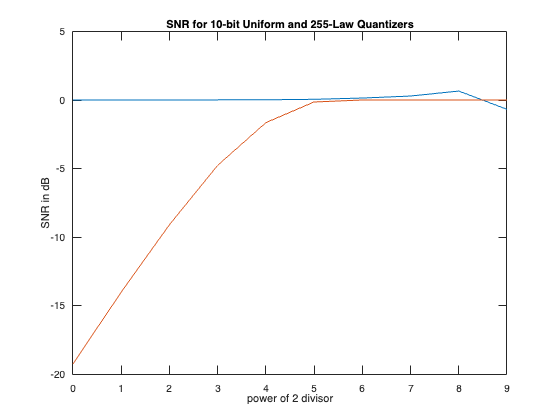

addpath("speech-quantization/")


fs = 8000;      
t = 0:1/fs:1;  
f = 1000;         

s = sin(2 * pi * f * t);

qplot(s5,10,255,10);

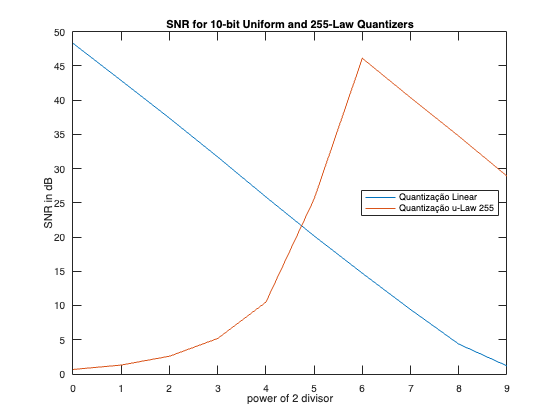

qplot_new(s5,10,255,10);
legend("Quantização Linear","Quantização u-Law 255");
legend('Location','east');

Função qplot alterada para nb

its até nbits-6 em $\mu$-Law. 

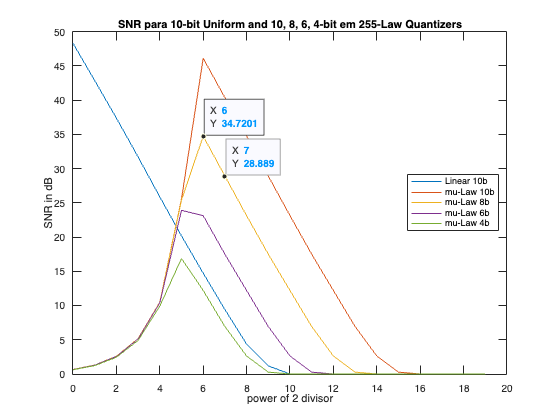

qplot_alt(s5,10,255,20);